# Example Feature Generation

This script is intended to service as an example of how to load, process, and generate features from the audio file. It will also show the table data type in MATLAB, which is similar to the dataframe in R and Python. 

## List files

Find all data files in the '\EnvNoiseDetector\data\DataExamples' directory. 

% Find data examples directory
basedir = fileparts(pwd);
datadir = fullfile(basedir,'data','DataExamples');

% List all audio files
audiofiles = struct2table(dir(fullfile(datadir,'*.wav')));
audiofiles.date = datetime(audiofiles.date);

% Load table of the audio file labels
audiolabels = readtable(fullfile(datadir,'FileDescriptions.xlsx'),'TextType','string');

% Convert data types
audiolabels.AircraftPresent = audiolabels.AircraftPresent == "Y";
audiolabels.Contaminated = audiolabels.Contaminated == "Y";

## Processing parameters

List and define processing parameters.

% record or block duration (s)
tblock = 1;

% fractional overlap between blocks, 0 <= foverlap <= 1
foverlap = 0.25;

% frequency limits for octave 
freqlim = [30 20000];

## Load audio file

Load and work with one audio file.

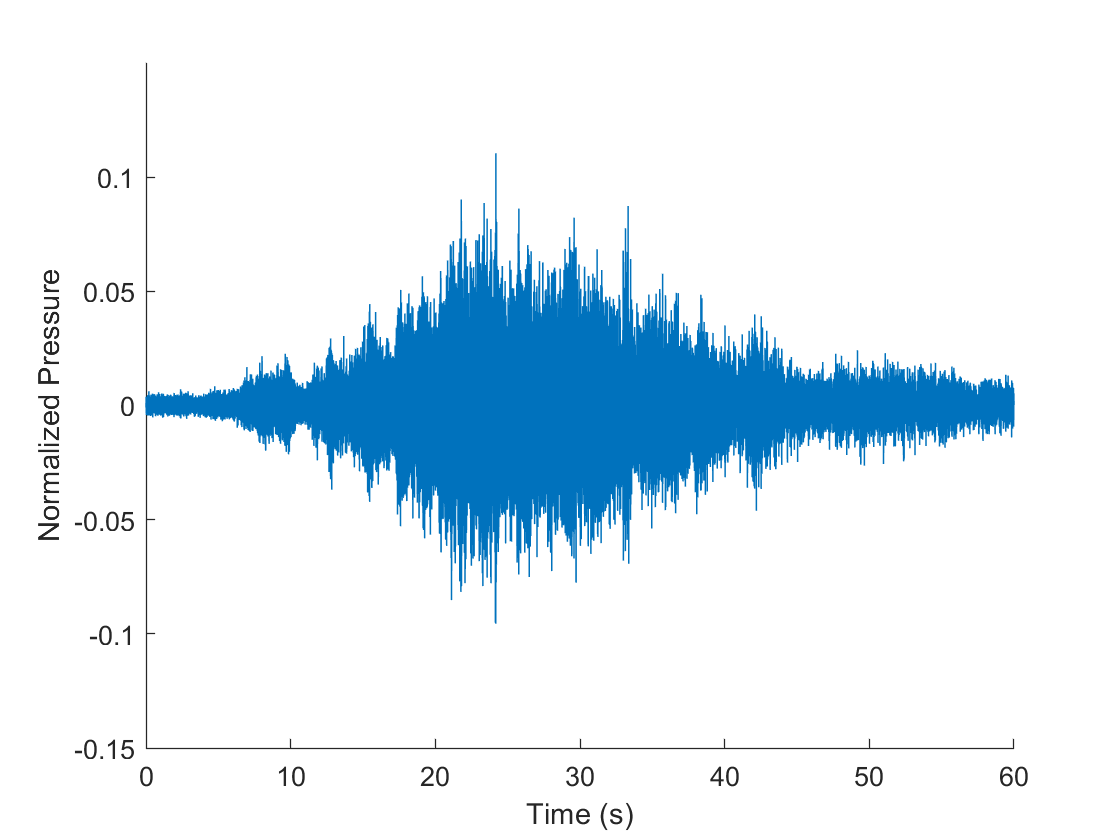

% Pick one file, load, and play
%filename = audiofiles.name{1};
filename = 'plane08.wav';

[x,fs] = audioread(fullfile(datadir,filename));

% sound(x,fs)

xcontaminated = audiolabels.Contaminated(audiolabels.FIleName == string(filename));

% Plot
t = (0:length(x)-1)'/fs;
figure
plot(t,x)
xlabel('Time (s)')
ylabel('Normalized Pressure')
ylim([-0.15 0.15])
box off

## Process audio signal

Process the audio signal according to the processing parameters. 

% Convert processing parameters to samples
nblock = tblock*fs;
noverlap = round(foverlap*nblock);

xblock = spectralReshape(x,noverlap,nblock);


## Generate features

Pick a method and generate features.

% Process each block with octave band spectrum
[pxx,fc] = poctave(xblock,fs,'FrequencyLimits',freqlim);

% Normalize the octave spectrum to remove the absolute power levels and retain only the shape
pxx = pxx./sum(pxx);

% Create table for classifier
xtable = array2table(pxx','VariableNames',"feature" + string(1:length(fc)));
xtable.contaminated = repmat(xcontaminated,height(xtable),1);


Add plot to visualized the changes in the octave spectrum. Shading is used to indicated the relative time the spectrum represents. The darker the line the more recent in time the spectrum is from. 

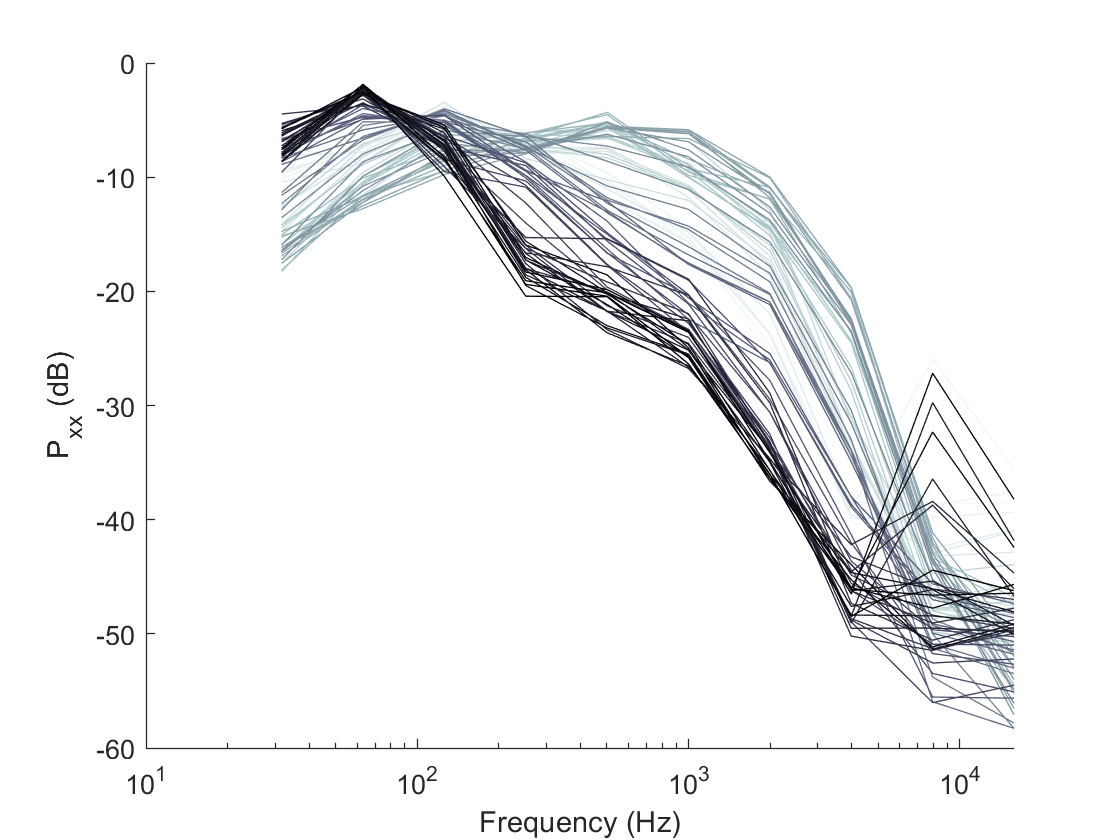

% Plot octave spectrum
cbone = bone(size(pxx,2));
hf = figure;
axes(hf,'XScale','log')
hold on;
for iblock = 1:size(pxx,2)
    semilogx(fc,10*log10(pxx(:,iblock)),'Color',cbone(end+1-iblock,:))
end
hold off;
xlabel('Frequency (Hz)')
ylabel('P_{xx} (dB)')

## Bird call

Now, let's look at a bird call. 

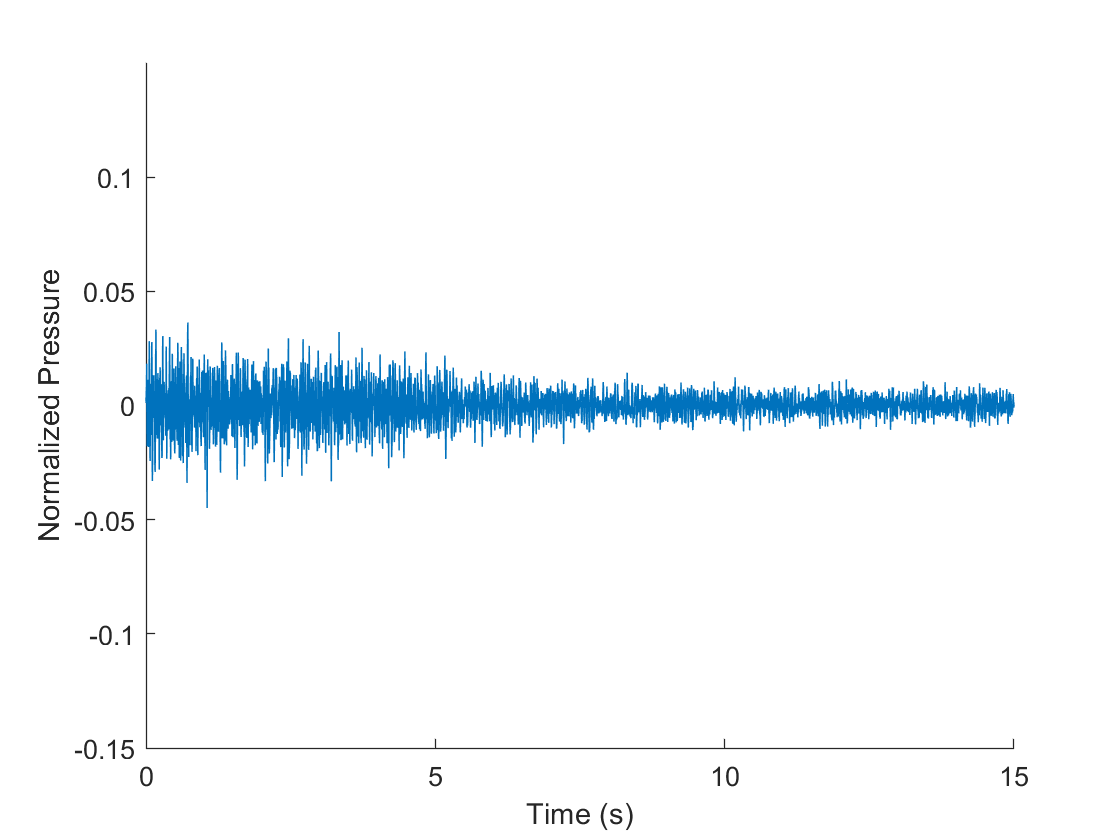

% Filename
filename = 'bird01.wav';

[x,fs] = audioread(fullfile(datadir,filename));

% sound(x,fs)

xcontaminated = audiolabels.Contaminated(audiolabels.FIleName == string(filename));

% Plot
t = (0:length(x)-1)'/fs;
figure
plot(t,x)
xlabel('Time (s)')
ylabel('Normalized Pressure')
ylim([-0.15 0.15])
box off

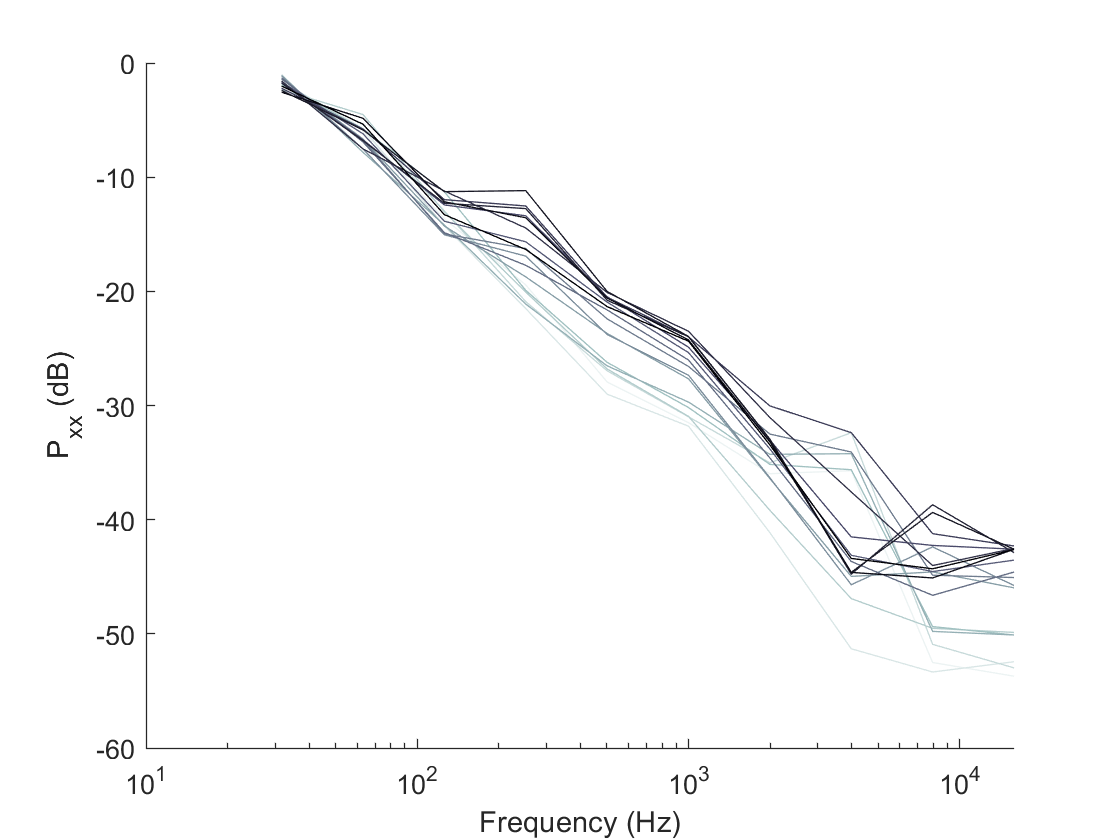


% Convert processing parameters to samples
nblock = tblock*fs;
noverlap = round(foverlap*nblock);

xblock = spectralReshape(x,noverlap,nblock);

% Process each block with octave band spectrum
[pxx,fc] = poctave(xblock,fs,'FrequencyLimits',freqlim);

% Normalize the octave spectrum to remove the absolute power levels and retain only the shape
pxx = pxx./sum(pxx);

% Create table for classifier
xtable = array2table(pxx','VariableNames',"feature" + string(1:length(fc)));
xtable.contaminated = repmat(xcontaminated,height(xtable),1);

% Plot octave spectrum
cbone = bone(size(pxx,2));
hf = figure;
axes(hf,'XScale','log')
hold on;
for iblock = 1:size(pxx,2)
    semilogx(fc,10*log10(pxx(:,iblock)),'Color',cbone(end+1-iblock,:))
end
hold off;
xlabel('Frequency (Hz)')
ylabel('P_{xx} (dB)')

## Classification

Now, try classification using the traditional algorithms. 

% Call the classification learner app
% Won't recognize the contimination variable as the response variable
% unless there is some variation in it. 
classificationLearner